% Create a |ryze| object.
%
ryzeObj = ryze();

cameraObj = camera(ryzeObj);
%  
serverList = opcuaserverinfo('opc.tcp://LAPTOP-3JNI0QV6:53530/OPCUA/SimulationServer')

serverList = OPC UA ServerInfo 'SimulationServer@LAPTOP-3JNI0QV6':

   Connection Information:
               Hostname: 'LAPTOP-3JNI0QV6'
                   Port: 53530
              Endpoints: [1×11 opc.ua.EndpointDescription]

   Security Information:
    BestMessageSecurity: SignAndEncrypt
    BestChannelSecurity: Aes256_Sha256_RsaPss
         UserTokenTypes: {'Anonymous'  'Username'  'Certificate'}


sampleServerInfo = findDescription(serverList, 'Simulation')

sampleServerInfo = OPC UA ServerInfo 'SimulationServer@LAPTOP-3JNI0QV6':

   Connection Information:
               Hostname: 'LAPTOP-3JNI0QV6'
                   Port: 53530
              Endpoints: [1×11 opc.ua.EndpointDescription]

   Security Information:
    BestMessageSecurity: SignAndEncrypt
    BestChannelSecurity: Aes256_Sha256_RsaPss
         UserTokenTypes: {'Anonymous'  'Username'  'Certificate'}


uaClient = opcua('localhost', 53530);
uaClient = opcua(sampleServerInfo)

uaClient = OPC UA Client:

   Server Information:
                     Name: 'SimulationServer@LAPTOP-3JNI0QV6'
                 Hostname: 'LAPTOP-3JNI0QV6'
                     Port: 53530
              EndpointUrl: 'opc.tcp://LAPTOP-3JNI0QV6:53530/OPCUA/SimulationServer'

   Connection Information:
                  Timeout: 10
                   Status: 'Disconnected'
              ServerState: '<Not connected>'

   Security Information:
      MessageSecurityMode: SignAndEncrypt
    ChannelSecurityPolicy: Aes256_Sha256_RsaPss
                Endpoints: [1×11 opc.ua.EndpointDescription]


status = uaClient.Status

status = 'Disconnected'


isConnected(uaClient)

ans = logical
   0


% Once you connect the client to the server, additional properties from the server are displayed.
connect(uaClient)
uaClient

uaClient = OPC UA Client:

   Server Information:
                       Name: 'SimulationServer@LAPTOP-3JNI0QV6'
                   Hostname: 'LAPTOP-3JNI0QV6'
                       Port: 53530
                EndpointUrl: 'opc.tcp://LAPTOP-3JNI0QV6:53530/OPCUA/SimulationServer'

   Connection Information:
                    Timeout: 10
                     Status: 'Connected'
                ServerState: 'Running'

   Security Information:
        MessageSecurityMode: SignAndEncrypt
      ChannelSecurityPolicy: Aes256_Sha256_RsaPss
                  Endpoints: [1×11 opc.ua.EndpointDescription]

   Server Limits:
              MinSampleRate: 0 sec
               MaxReadNodes: 0
              MaxWriteNodes: 0
        MaxHistoryReadNodes: 0
    MaxHistoryValuesPerNode: 0


uaClient = opcua('localhost', 53530);
connect(uaClient);

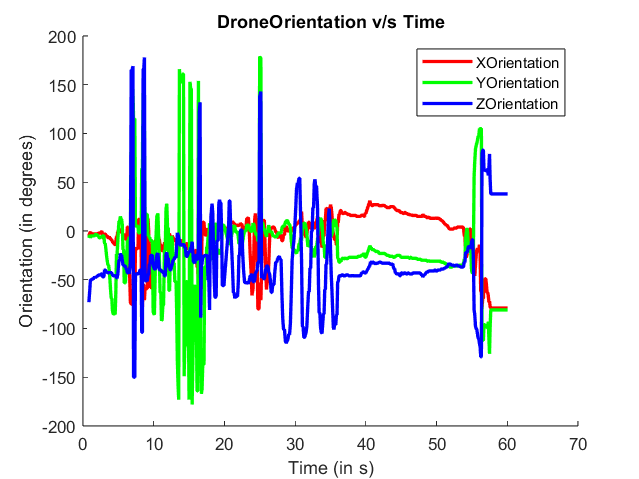

Unable to receive response from the drone. Ensure that the computer is connected to the drone's WiFi network and
try again.

initialValue = 0;  % Initialize with a value that is not possible for 'value'

while true
    tempVariable = findNodeByName(uaClient.Namespace, 'Request', '-once');
    [value, timestamp, quality] = readValue(uaClient, tempVariable);
    tempVariable1 = findNodeByName(uaClient.Namespace, 'Hx', '-once');
    tempVariable2 = findNodeByName(uaClient.Namespace, 'Hy', '-once');
    tempVariable3 = findNodeByName(uaClient.Namespace, 'Hz', '-once');
    
    % Check if the value has changed
    if value ~= initialValue
        % Reset the flag when the value changes
        initialValue = value;

        % Execute the corresponding block
        if value == 1
            takeoff(ryzeObj);
        elseif value == 5
            turn(ryzeObj, deg2rad(90));
            
        elseif value == 2
            video = preview(cameraObj);
            name = "tiny-yolov4-coco";
            detector = yolov4ObjectDetector(name);
            var=1;
            while var<=120
                frame = snapshot(cameraObj);
                [bboxes,scores,labels] = detect(detector, frame);
                detectedFrame = insertObjectAnnotation(frame, 'rectangle', bboxes, labels);
                imshow(detectedFrame);
                var=var+1;
            end
        elseif value == 3
            open('trackBall.m')
            tim = tic;
            duration = 60;
            minGreenIntensity = 40;
            minOffset = 30;
            while toc(tim) < duration
                img = snapshot(cameraObj);
                trackBall(ryzeObj, img, minGreenIntensity, minOffset);
                pause(0.1);
            end
        elseif value == 4
            f = figure;
            hx = animatedline('Color', 'r', 'LineWidth', 2);
            hy = animatedline('Color', 'g', 'LineWidth', 2);
            hz = animatedline('Color', 'b', 'LineWidth', 2);
            title('DroneOrientation v/s Time');
            xlabel('Time (in s)');
            ylabel('Orientation (in degrees)');
            legend('XOrientation', 'YOrientation', 'ZOrientation');
            orientationData = cell(1, 3);
            edgeIndex = 1;
            distance = 5;
            speed = 0.25;
            tObj = tic;
            while edgeIndex <= 4
                % Move the drone unblocking the command line
                tplot = tic;
                moveforward(ryzeObj, 'Distance', distance, 'Speed', speed, 'WaitUntilDone', false);
                % Plot orientation while drone is moving
                while toc(tplot) < distance/speed
                    orientation = rad2deg(readOrientation(ryzeObj));
                                writeValue(uaClient, tempVariable1, orientation(2));
            writeValue(uaClient, tempVariable2, orientation(3));
            writeValue(uaClient, tempVariable3, orientation(1));
                    tStamp = toc(tObj);
                    addpoints(hx, tStamp, orientation(2));
                    addpoints(hy, tStamp, orientation(3));
                    addpoints(hz, tStamp, orientation(1));
                    drawnow;
                    orientationData{end + 1, 1} = tStamp;
        orientationData{end, 2} = orientation(2);
        orientationData{end, 3} = orientation(3);
        orientationData{end, 4} = orientation(1);
                end
                edgeIndex = edgeIndex + 1;
            end
            save('orientation_data.mat', 'orientationData');
        elseif value == 6
            moveforward(ryzeObj, 'Distance', 5, 'Speed', 0.5, 'WaitUntilDone', false);
        end
    end
end